% THETA BETA MACH RELATIONS

% PART OF THE CODE FOR
% AERO 97009 - FINAL YEAR PROJECT
% CONCERNING BUSEMANN BIPLANES

% THOMAS CROSS
% DECEMBER 2020

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Based on Code extracted from:

% Sambit Supriya Dash (2020)
% %Theta-Beta-MachNo Relation (Plot) for Oblique Shock Waves
% https://www.mathworks.com/matlabcentral/fileexchange/72590-theta-beta-machno-relation-plot-for-oblique-shock-waves)
% MATLAB Central File Exchange
% Retrieved December 20, 2020.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, %title, %%legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultlegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


gamma = 1.4;                                 % Specific heat ratio for air
beta = 0:0.2:90;                     % Range for shock wave angle
%Machs = logspace(0,1,100); 
%Machs=[1:0.1:10]; 
%Machs=[1:0.1:3,3.2:0.2:4,5,6,8,10,100]; 
Machs = linspace(1,10,1000) %works well
cmap=colormap(parula(length(Machs)));
%m = 0;    
                                         % theta (=flow deflection angle)
for m = 1:length(Machs) %1:0.2:10                        % Upstream Mach Number
    M1 = Machs(m);
    %m = m+1;
    %================================
    %     theta-beta-M relation
    %================================
    Nr = ((M1^2)*((sind(beta)).^2))-1;    
    Dr = ((gamma+(cosd(2*beta)))*M1^2)+2;
    theta = atand(2*cotd(beta).*Nr./Dr);
    %================================
    %      max. theta for a M1
    %================================
    a(m) = max(theta);                   % max theta for the Mach No.
    b(m) = beta(find(theta==a(m)));      % find the beta for max. theta
    plot(theta,beta,'-','Color',cmap(m,:))
    hold on
end
     c = colorbar('Ticks',[0,1], 'TickLabels',{'1','\infty'},'location','east');
set(c,'TickLabelInterpreter','latex','TickDirection','both')
%set(c, 'ylim', [0 0.16]); % set your range here
ylabel(c,'Mach Number, $\textrm{Ma}$ / [Dimensionless]','Interpreter','latex','FontSize',lsize)
plot(a,b,'--','Color',red,'Linewidth',width)
xlabel('Deflection Angle, $\theta$ / $^{\circ}$','FontSize',lsize)
ylabel('Shock Angle, $\beta$ / $^{\circ}$','FontSize',lsize)
%title("\textbf{\theta-\beta-Mach Relations for air ($\gamma=1.4$)}")
axis([0 50 0 90])
grid on; box on; hold on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

beta = 0.1:0.5:90.1; 
theta = 0.1:0.5:45.1;
[X,Y]=meshgrid(theta,beta);
Mach=zeros(length(beta),length(theta))

for i=1:length(beta)
    for j=1:length(theta)
        Beta=beta(i);
        Theta=theta(j);
fcn = @(M) ((2*cotd(Beta)) .* ((((M.^2).*((sind(Beta)).^2))-1) ./ (((gamma+(cosd(2*Beta))).*M^2)+2)))-tand(Theta);
Mach(i,j) = -1./fzero(fcn,0);
    end
end

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is NaN.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is NaN.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is NaN.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is NaN.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interv

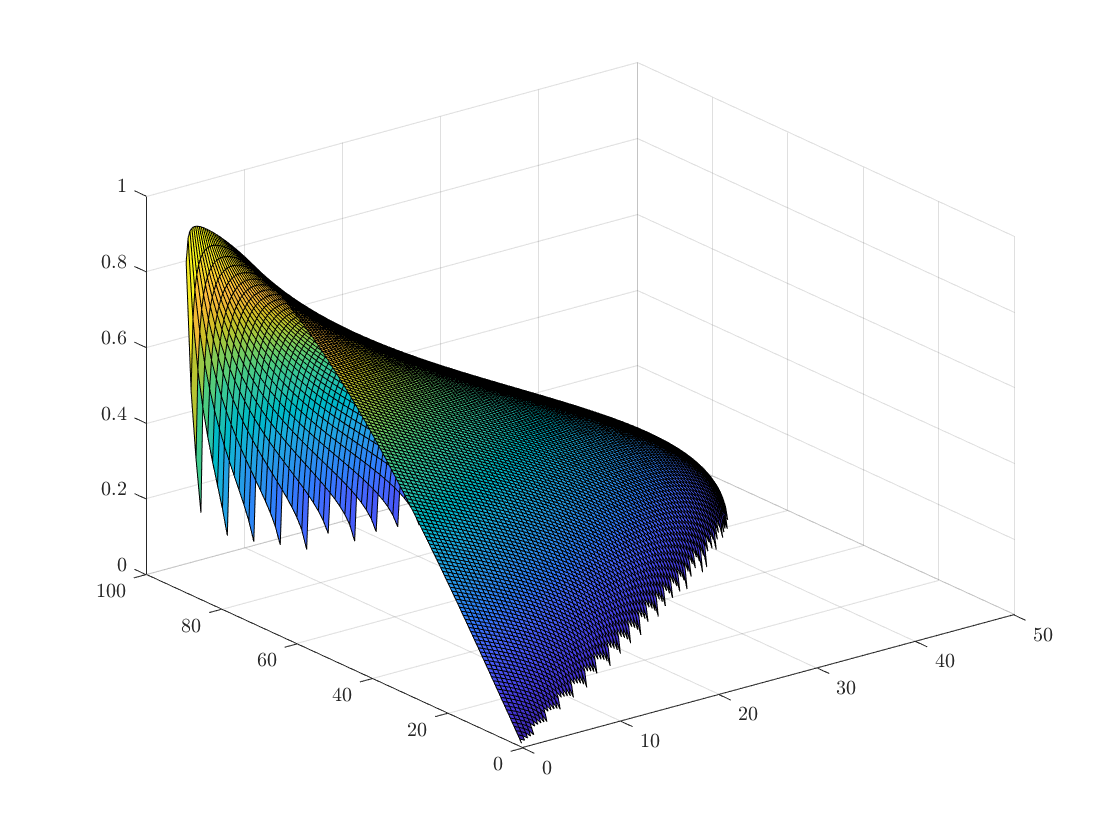

figure
surf(X,Y,Mach)

%view(2)

M = 1./Mach;
%M(M > 10) = NaN;
figure
plot(a,b,'--','Color',red,'Linewidth',width)
hold on
v = [1,1.1,1.2,1.3,1.4,1.5,1.7,2,2.5,3.5,5,10];
[C,h] = contour(X,Y,M,v,'ShowText','on',"LineWidth",width)

C =     1.1000    0.1000    0.1527    0.2375    0.3208    0.4027    0.4833    0.5623    0.6000    0.6401    0.7165    0.7906    0.8621    0.9310    0.9970    1.0600    1.1000    1.1198    1.1763    1.2291    1.2780    1.3229    1.3635    1.3996    1.4312    1.4580    1.4798    1.4966    1.5081    1.5142    1.5148    1.5097    1.4988    1.4820    1.4592    1.4302    1.3950    1.3534    1.3054    1.2509    1.1898    1.1220    1.1000    1.0474    0.9660    0.8777    0.7825    0.6803    0.6000    0.5711
   53.0000   89.3091   89.1000   88.6000   88.1000   87.6000   87.1000   86.6000   86.3392   86.1000   85.6000   85.1000   84.6000   84.1000   83.6000   83.1000   82.7573   82.6000   82.1000   81.6000   81.1000   80.6000   80.1000   79.6000   79.1000   78.6000   78.1000   77.6000   77.1000   76.6000   76.1000   75.6000   75.1000   74.6000   74.1000   73.6000   73.1000   72.6000   72.1000   71.6000   71.1000   70.6000   70.4505   70.1000   69.6000   69.1000   68.6000   68.1000   67.7306   67

h =   Contour with properties:

    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 1.5000
         Fill: off
    LevelList: [1 1.1000 1.2000 1.3000 1.4000 1.5000 1.7000 2 2.5000 3.5000 5 10]
        XData: [181×91 double]
        YData: [181×91 double]
        ZData: [181×91 double]

  Show all properties


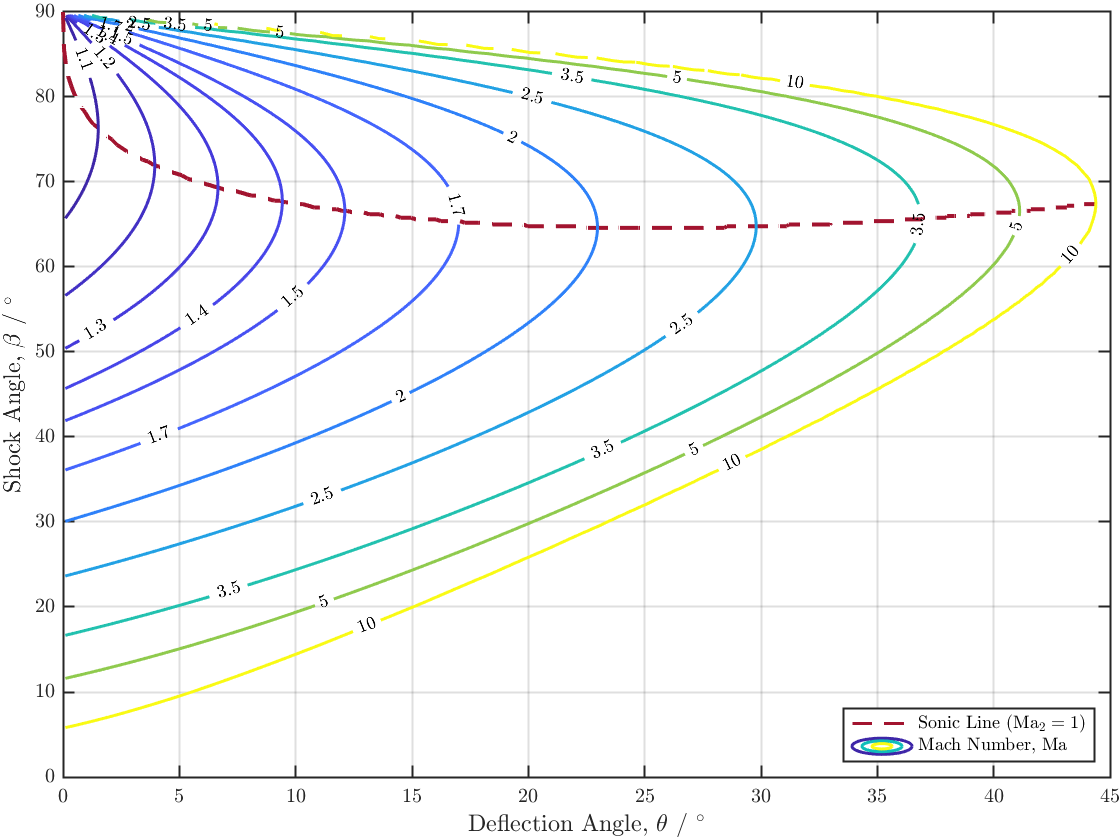

%clabel(C,h,'manual')
clabel(C,h,v,'FontSize',legsize,'LabelSpacing',200,'Interpreter','latex')
set(gca,'ColorScale','log')
% c=colorbar;
% set(c,'TickLabelInterpreter','latex','TickDirection','both')
% ylabel(c,'Mach Number, $\textrm{Ma}$ / [Dimensionless]','Interpreter','latex','FontSize',lsize)
grid on; box off; hold on
xlabel('Deflection Angle, $\theta$ / $^{\circ}$','FontSize',lsize)
ylabel('Shock Angle, $\beta$ / $^{\circ}$','FontSize',lsize)
%title("\textbf{\theta-\beta-Mach Relations for air ($\gamma=1.4$)}")
axis([0 45 0 90])
grid on; box on; hold on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
legend(["Sonic Line ($\textrm{Ma}_2=1$)"],"Mach Number, $\textrm{Ma}$",'Location',"southeast",'FontSize',legsize)
H=gca; H.LineWidth=1;
hold off

%saveas(gcf,'theta-beta-mach.png'

%%%%%%%%%%%%%%%%%
%Sambit Supriya Dash (2020)
% %Theta-Beta-MachNo Relation (Plot) for Oblique Shock Waves
% https://www.mathworks.com/matlabcentral/fileexchange/72590-theta-beta-machno-relation-plot-for-oblique-shock-waves)
% MATLAB Central File Exchange
% Retrieved December 20, 2020.
% % 
% % gamma = 1.4;                                 % Specific heat ratio for air
% % beta = 0:0.5:90;                     % Range for shock wave angle
% % m = 0;    
% %                                          % theta (=flow deflection angle)
% % for M1 = [1,1.05,1.1:0.1:2,2.25,2.5,3,4,5,6,8,10]%1:0.2:10                        % Upstream Mach Number
% %     x=length(M1);
% %     m = m+1;
% %     %================================
% %     %     theta-beta-M relation
% %     %================================
% %     Nr = ((M1^2)*((sind(beta)).^2))-1;    
% %     Dr = ((gamma+(cosd(2*beta)))*M1^2)+2;
% %     theta = atand(2*cotd(beta).*Nr./Dr);
% %     %================================
% %     %      max. theta for a M1
% %     %================================
% %     a(m) = max(theta);                   % max theta for the Mach No.
% %     b(m) = beta(find(theta==a(m)));      % find the beta for max. theta
% %     plot(theta,beta,'-','Color',[0 0.4470 0.7410])
% %     hold on
% % end
% % plot(a,b,'--','Color',[0.8500 0.3250 0.0980],'Linewidth',1.5)
% % xlabel('Deflection Angle \theta')
% % ylabel('Shock Angle \beta')
% % grid on
% % box off
% % title("\theta-\beta-Mach Relations for air (\gamma=1.4)")
% % axis([0 50 0 90])
% % hold off